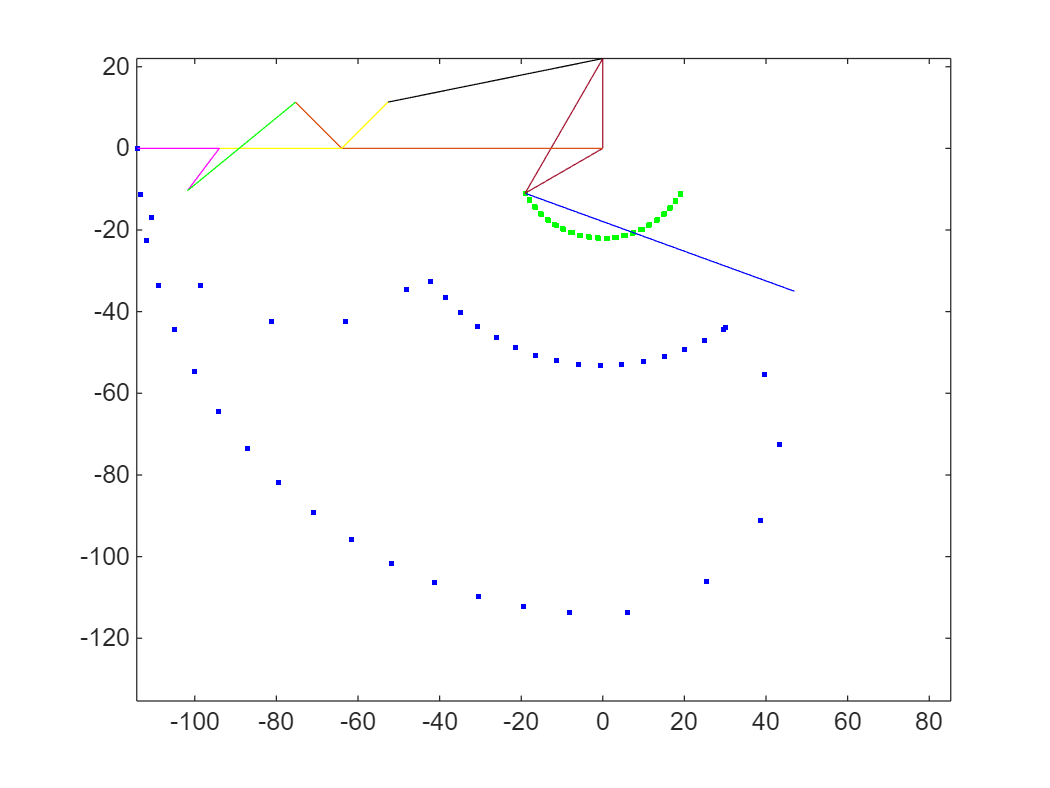

clc;
syms thetha_1
r = 22; l=66;
%point Link 4
Ex = piecewise(thetha_1>=0 & thetha_1<=2*pi/3, r*cos(pi/2+thetha_1), thetha_1>2*pi/3 & thetha_1<=4*pi/3, r*cos(7*pi/6), thetha_1>4*pi/3 & thetha_1<=6*pi/3, r*cos(7*pi/6+(4*pi/3-thetha_1)), r*cos(pi/2)); % 4-Bar_Input
Ey = piecewise(thetha_1>=0 & thetha_1<=2*pi/3, r*sin(pi/2+thetha_1), thetha_1>2*pi/3 & thetha_1<=4*pi/3, r*sin(7*pi/6), thetha_1>4*pi/3 & thetha_1<=6*pi/3, r*sin(7*pi/6+(4*pi/3-thetha_1)), r*sin(pi/2));
Bx = piecewise(thetha_1>=0 & thetha_1<=2*pi/3, r*cos(7*pi/6+thetha_1), thetha_1>2*pi/3 & thetha_1<=4*pi/3, r*cos(11*pi/6), thetha_1>4*pi/3 & thetha_1<=6*pi/3, r*cos(11*pi/6+(4*pi/3-thetha_1)), r*cos(7*pi/6)); % Crank(Slider)
By = piecewise(thetha_1>=0 & thetha_1<=2*pi/3, r*sin(7*pi/6+thetha_1), thetha_1>2*pi/3 & thetha_1<=4*pi/3, r*sin(11*pi/6), thetha_1>4*pi/3 & thetha_1<=6*pi/3, r*sin(11*pi/6+(4*pi/3-thetha_1)), r*sin(7*pi/6)); 
%point slider
Ax = Bx+sqrt(l^2-By-r/2); 
Ay = -35;
%point Link 5
Fx = piecewise(thetha_1>=0 & thetha_1<=pi/2, -64*cos(thetha_1), thetha_1>pi/2 & thetha_1<=4*pi/3, -64*cos(pi/2), thetha_1>4*pi/3 & thetha_1<=11*pi/6, -64*cos(pi/2+(4*pi/3-thetha_1)), -64*cos(0)); %Red(Fing1)
Fy = piecewise(thetha_1>=0 & thetha_1<=pi/2, -64*sin(thetha_1), thetha_1>pi/2 & thetha_1<=4*pi/3, -64*sin(pi/2), thetha_1>4*pi/3 & thetha_1<=11*pi/6, -64*sin(pi/2+(4*pi/3-thetha_1)), -64*sin(0));
%point Link 7
Ix = piecewise(thetha_1>=0 & thetha_1<=pi/2, Fx-30*cos(thetha_1), thetha_1>pi/2 & thetha_1<=2*pi/3, Fx-30*cos(pi/2+3*(thetha_1-pi/2)), thetha_1>2*pi/3 & thetha_1<=4*pi/3, Fx-30*cos(pi), thetha_1>4*pi/3 & thetha_1<=11*pi/6, Fx-30*cos(pi+(4*pi/3-thetha_1)), thetha_1>11*pi/6 & thetha_1<=6*pi/3, Fx-30*cos(pi/2+3*(11*pi/6-thetha_1)), Fx-30*cos(0));
Iy = piecewise(thetha_1>=0 & thetha_1<=pi/2, Fy-30*sin(thetha_1), thetha_1>pi/2 & thetha_1<=2*pi/3, Fy-30*sin(pi/2+3*(thetha_1-pi/2)), thetha_1>2*pi/3 & thetha_1<=4*pi/3, Fy-30*sin(pi), thetha_1>4*pi/3 & thetha_1<=11*pi/6, Fy-30*sin(pi+(4*pi/3-thetha_1)), thetha_1>11*pi/6 & thetha_1<=6*pi/3, Fy-30*sin(pi/2+3*(11*pi/6-thetha_1)), Fy-30*sin(0));
%point Link 6
Ixn1 = piecewise(thetha_1>=0 & thetha_1<=pi/2, Fx+16*cos(pi/4+thetha_1), thetha_1>pi/2 & thetha_1<=2*pi/3, Fx+16*cos(3*pi/4+3*(thetha_1-pi/2)), thetha_1>2*pi/3 & thetha_1<=4*pi/3, Fx+16*cos(pi/4+pi), thetha_1>4*pi/3 & thetha_1<=11*pi/6, Fx+16*cos(5*pi/4+(4*pi/3-thetha_1)), thetha_1>11*pi/6 & thetha_1<=6*pi/3, Fx+16*cos(3*pi/4+3*(11*pi/6-thetha_1)), Fx+16*cos(pi/4));
Iyn1 = piecewise(thetha_1>=0 & thetha_1<=pi/2, Fy+16*sin(pi/4+thetha_1), thetha_1>pi/2 & thetha_1<=2*pi/3, Fy+16*sin(3*pi/4+3*(thetha_1-pi/2)), thetha_1>2*pi/3 & thetha_1<=4*pi/3, Fy+16*sin(pi/4+pi), thetha_1>4*pi/3 & thetha_1<=11*pi/6, Fy+16*sin(5*pi/4+(4*pi/3-thetha_1)), thetha_1>11*pi/6 & thetha_1<=6*pi/3, Fy+16*sin(3*pi/4+3*(11*pi/6-thetha_1)), Fy+16*sin(pi/4));
%point Link 8
Ixn2 = piecewise(thetha_1>=0 & thetha_1<=pi/2, Fx+16*cos(3*pi/4+thetha_1), thetha_1>pi/2 & thetha_1<4*pi/3, Fx+16*cos(3*pi/4+pi/2), thetha_1>4*pi/3 & thetha_1<=11*pi/6, Fx+16*cos(5*pi/4+(4*pi/3-thetha_1)), Fx+16*cos(3*pi/4));
Iyn2 = piecewise(thetha_1>=0 & thetha_1<=pi/2, Fy+16*sin(3*pi/4+thetha_1), thetha_1>pi/2 & thetha_1<4*pi/3, Fy+16*sin(3*pi/4+pi/2), thetha_1>4*pi/3 & thetha_1<=11*pi/6, Fy+16*sin(5*pi/4+(4*pi/3-thetha_1)), Fy+16*sin(3*pi/4));
Hx = piecewise(thetha_1>=0 & thetha_1<=pi/2, Ix-13*cos(53*pi/180+thetha_1), thetha_1>pi/2 & thetha_1<=2*pi/3, Ix-13*cos(143*pi/180+6*(thetha_1-pi/2)), thetha_1>2*pi/3 & thetha_1<=4*pi/3, Ix-13*cos(53*pi/180+3*pi/2), thetha_1>4*pi/3 & thetha_1<=11*pi/6, Ix-13*cos(323*pi/180+(4*pi/3-thetha_1)), thetha_1>11*pi/6 & thetha_1<=6*pi/3, Ix-13*cos(233*pi/180+6*(11*pi/6-thetha_1)), Ix-13*cos(53*pi/180));
Hy = piecewise(thetha_1>=0 & thetha_1<=pi/2, Iy-13*sin(53*pi/180+thetha_1), thetha_1>pi/2 & thetha_1<=2*pi/3, Iy-13*sin(143*pi/180+6*(thetha_1-pi/2)), thetha_1>2*pi/3 & thetha_1<=4*pi/3, Iy-13*sin(53*pi/180+3*pi/2), thetha_1>4*pi/3 & thetha_1<=11*pi/6, Iy-13*sin(323*pi/180+(4*pi/3-thetha_1)), thetha_1>11*pi/6 & thetha_1<=6*pi/3, Iy-13*sin(233*pi/180+6*(11*pi/6-thetha_1)), Iy-13*sin(53*pi/180));
%point Link 9
Jx = piecewise(thetha_1>=0 & thetha_1<=pi/2, Ix-20*cos(thetha_1), thetha_1>pi/2 & thetha_1<=2*pi/3, Ix-20*cos(pi/2+6*(thetha_1-pi/2)), thetha_1>2*pi/3 & thetha_1<=4*pi/3, Ix-20*cos(3*pi/2), thetha_1>4*pi/3 & thetha_1<=11*pi/6, Ix-20*cos(3*pi/2+(4*pi/3-thetha_1)), thetha_1>11*pi/6 & thetha_1<=6*pi/3, Ix-20*cos(pi+6*(11*pi/6-thetha_1)), Ix-20*cos(0));
Jy = piecewise(thetha_1>=0 & thetha_1<=pi/2, Iy-20*sin(thetha_1), thetha_1>pi/2 & thetha_1<=2*pi/3, Iy-20*sin(pi/2+6*(thetha_1-pi/2)), thetha_1>2*pi/3 & thetha_1<=4*pi/3, Iy-20*sin(3*pi/2), thetha_1>4*pi/3 & thetha_1<=11*pi/6, Iy-20*sin(3*pi/2+(4*pi/3-thetha_1)), thetha_1>11*pi/6 & thetha_1<=6*pi/3, Iy-20*sin(pi+6*(11*pi/6-thetha_1)), Iy-20*sin(0));
%link
link3 = @(t) plot([subs(Ax,t) subs(Bx,t)], [subs(Ay,t) subs(By,t)],"b");
link4 = @(t) plot([0 subs(Bx,t) subs(Ex,t) 0],[0 subs(By,t) subs(Ey,t) 0],"Color",[0.6350 0.0780 0.1840]);
link5 = @(t) plot([0 subs(Fx,t) subs(Ixn2,t)], [0 subs(Fy,t) subs(Iyn2,t)],"Color",[0.8500 0.3250 0.0980]);
link6 = @(t) plot([subs(Ex,t) subs(Ixn1,t)], [subs(Ey,t) subs(Iyn1,t)],"k");
link8 = @(t) plot([subs(Ixn1,t) subs(Fx,t) subs(Ix,t)], [subs(Iyn1,t) subs(Fy,t) subs(Iy,t)],"y");
link9 = @(t) plot([subs(Hx,t) subs(Ix,t) subs(Jx,t)], [subs(Hy,t) subs(Iy,t) subs(Jy,t)],"m");
link7 = @(t) plot([subs(Ixn2,t) subs(Hx,t)], [subs(Iyn2,t) subs(Hy,t)], "g");
%animation
figure()
plot(subs(Bx,0:0.1:2*pi),subs(By,0:0.1:2*pi),".g")
axis equal
hold on
plot(subs(Jx,0:0.1:2*pi),subs(Jy,0:0.1:2*pi),".b")
fanimator(link3)
fanimator(link4)
fanimator(link5)
fanimator(link6)
fanimator(link8)
fanimator(link9)
fanimator(link7)
hold off
playAnimation('SpeedFactor', 0.6)